1. Functie MATLAB pentru a calcula epsilonul masinii, cel mai mare numar reprezentabil in VF, cel mai mic numar normalizat/denormalizat in VF.

Stim ca un numar in calculator este reprezentat ca un sir continuu de biti. Putem astfel sa determinam constantele mentionate "abuzand" reprezentarea in memorie a calculatorului, prin experimente succesive.

In VF, un numar este reprezentat astfel:

$x = \pm c_0.c_1c_2...c_{p-1} * \beta^{e}$, unde c0.c1c2...cp-1 se numeste "mantisa", p se numeste "precizie" (trunchiere in memoria calculatorului) iar Beta se numeste "baza" (mereu para), iar e se numeste "exponent".

0 se reprezinta ca $1.0 * \beta^{e_{min}}$, $e_{min} \le e \le e_{max}$ (minim/maxim de cifre ce pot fi reprezentate pe masina).

computeVFConstants();

My eps: 2.2204460492503131e-16
Machine's eps: 2.2204460492503131e-16
Error: 0.0000000000000000e+00

My realmax: 1.7976931348623157e+308
Machine's realmax: 1.7976931348623157e+308
Error: 0.0000000000000000e+00

My normalized realmin: 2.2250738585072014e-308
Machine's normalized realmin: 2.2250738585072014e-308
Error: 0.0000000000000000e+00

My denormalized realmin: 4.9406564584124654e-324
Machine's denormalized realmin: 4.9406564584124654e-324
Error: 0.0000000000000000e+00



2. $\sin(x)$si $\cos(x)$folosind formula lui Taylor:


$$\sin(x) = x - \frac{x^3}{3!} + \frac{x^5}{5!} - ... + (-1)^n * \frac{x^{2n+1}}{(2n+1)!}$$



$$cos(x) = 1 - \frac{x^2}{2} + \frac{x^4}{4} - ... + (-1)^n * \frac{x^{2n}}{(2n)!}$$


[nsin1, bsin1, bbsin1] = sinTaylor(pi * 10);

x = 3.1415926535897931e+01
Normal sin(x)                            = -1.2246467991473533e-15
Base sin(x) using Taylor                 = 1.0356824470682769e-03
Better sin(x) using Taylor (with reduce) = 0.0000000000000000e+00

========= ERRORS =========
Normal vs. Base    = 1.0356824470695017e-03
Normal vs. Better  = 1.2246467991473533e-15
Base   vs. Better  = 1.0356824470682769e-03



[nsin2, bsin2, bbsin2] = sinTaylor(13 * pi / 2);

x = 2.0420352248333657e+01
Normal sin(x)                            = 1.0000000000000000e+00
Base sin(x) using Taylor                 = 9.9999999618870372e-01
Better sin(x) using Taylor (with reduce) = 1.0000000000000000e+00

========= ERRORS =========
Normal vs. Base    = 3.8112962785774585e-09
Normal vs. Better  = 4.4323046251973637e-79
Base   vs. Better  = 3.8112962785774585e-09



rad_range = linspace(0, 2*pi, 100);

% Plotting sin(x) with all methods
normal_sin_points = zeros(size(rad_range));
base_sin_points = zeros(size(rad_range));
better_sin_points = zeros(size(rad_range));

for i = 1:length(rad_range)
    [nsin, bsin, bbsin] = sinTaylor(rad_range(i));
    normal_sin_points(i) = nsin;
    base_sin_points(i) = bsin;
    better_sin_points(i) = bbsin;
end

x = 0.0000000000000000e+00
Normal sin(x)                            = 0.0000000000000000e+00
Base sin(x) using Taylor                 = 0.0000000000000000e+00
Better sin(x) using Taylor (with reduce) = 0.0000000000000000e+00

========= ERRORS =========
Normal vs. Base    = 0.0000000000000000e+00
Normal vs. Better  = 0.0000000000000000e+00
Base   vs. Better  = 0.0000000000000000e+00

x = 6.3466518254339258e-02
Normal sin(x)                            = 6.3423919656564506e-02
Base sin(x) using Taylor                 = 6.3423919656564506e-02
Better sin(x) using Taylor (with reduce) = 6.3423919656564506e-02

========= ERRORS =========
Normal vs. Base    = 0.0000000000000000e+00
Normal vs. Better  = 3.2101216967045412e-18
Base   vs. Better  = 3.2101216967045412e-18

x = 1.2693303650867852e-01
Normal sin(x)                            = 1.2659245357374926e-01
Base sin(x) using Taylor                 = 1.2659245357374926e-01
Better sin(x) using Taylor (with reduce) = 1.2659245357374926e-01

==

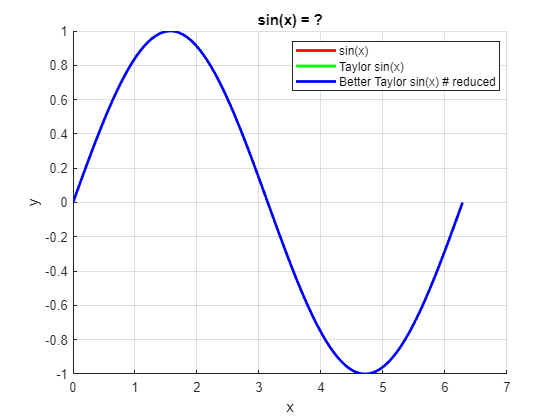

figure(1);
hold on;

plot(rad_range, normal_sin_points, 'r', 'LineWidth', 2, 'DisplayName', 'sin(x)');
plot(rad_range, base_sin_points, 'g', 'LineWidth', 2, 'DisplayName', 'Taylor sin(x)');
plot(rad_range, better_sin_points, 'b', 'LineWidth', 2, 'DisplayName', 'Better Taylor sin(x) # reduced');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('sin(x) = ?');

hold off;

[ncos1, bcos1, bbcos1] = cosTaylor(10*pi);

x = 3.1415926535897931e+01
Normal cos(x)                            = 1.0000000000000000e+00
Base cos(x) using Taylor                 = 9.9917746120308404e-01
Better cos(x) using Taylor (with reduce) = 1.0000000000000000e+00

========= ERRORS =========
Normal vs. Base    = 8.2253879691596143e-04
Normal vs. Better  = 0.0000000000000000e+00
Base   vs. Better  = 8.2253879691596143e-04



[ncos2, bcos2, bbcos2] = cosTaylor(13 * pi / 2);

x = 2.0420352248333657e+01
Normal cos(x)                            = -9.8033641995447082e-16
Base cos(x) using Taylor                 = 5.4984276314772759e-09
Better cos(x) using Taylor (with reduce) = 9.4152053883039252e-40

========= ERRORS =========
Normal vs. Base    = 5.4984286118136959e-09
Normal vs. Better  = 9.8033641995447082e-16
Base   vs. Better  = 5.4984276314772759e-09



% Plotting cos(x) with all methods
normal_cos_points = zeros(size(rad_range));
base_cos_points = zeros(size(rad_range));
better_cos_points = zeros(size(rad_range));

for i = 1:length(rad_range)
    [ncos, bcos, bbcos] = cosTaylor(rad_range(i));
    normal_cos_points(i) = ncos;
    base_cos_points(i) = bcos;
    better_cos_points(i) = bbcos;
end

x = 0.0000000000000000e+00
Normal cos(x)                            = 1.0000000000000000e+00
Base cos(x) using Taylor                 = 1.0000000000000000e+00
Better cos(x) using Taylor (with reduce) = 1.0000000000000000e+00

========= ERRORS =========
Normal vs. Base    = 0.0000000000000000e+00
Normal vs. Better  = 0.0000000000000000e+00
Base   vs. Better  = 0.0000000000000000e+00

x = 6.3466518254339258e-02
Normal cos(x)                            = 9.9798667647188444e-01
Base cos(x) using Taylor                 = 9.9798667647188444e-01
Better cos(x) using Taylor (with reduce) = 9.9798667647188444e-01

========= ERRORS =========
Normal vs. Base    = 0.0000000000000000e+00
Normal vs. Better  = 4.4338162365403820e-17
Base   vs. Better  = 4.4338162365403820e-17

x = 1.2693303650867852e-01
Normal cos(x)                            = 9.9195481283079534e-01
Base cos(x) using Taylor                 = 9.9195481283079534e-01
Better cos(x) using Taylor (with reduce) = 9.9195481283079534e-01

==

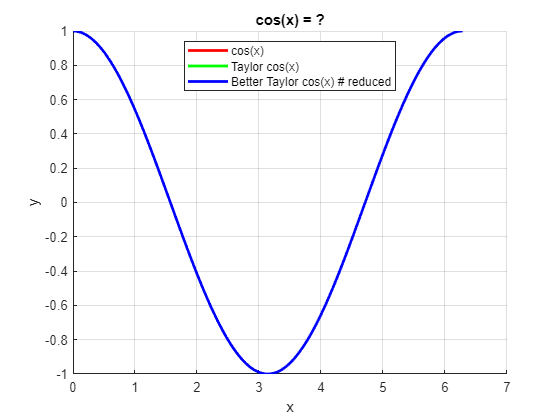


figure(2);
hold on;

plot(rad_range, normal_cos_points, 'r', 'LineWidth', 2, 'DisplayName', 'cos(x)');
plot(rad_range, base_cos_points, 'g', 'LineWidth', 2, 'DisplayName', 'Taylor cos(x)');
plot(rad_range, better_cos_points, 'b', 'LineWidth', 2, 'DisplayName', 'Better Taylor cos(x) # reduced');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('cos(x) = ?');

hold off;

3. $\sin(x)$ si $\cos(x)$folosind Aproximarea Pade. Pentru aceasta problema, aproximarea Pade de la laboratorul 1, care calculeaza si coeficientiii este singulara, astfel ca a trebuit o alta abordare. Abordarea pentru aceasta problema calculeaza coeficientii seriei Maclaurin inainte ca Aproximarea Pade sa fie calculata, pentru a evita rezolvarea unor matrici foarte greu de rezolvat sau chiar imposibil de rezolvat cu matematica "raw" din Matlab.

rad_range_pade = linspace(0, 10*pi, 100);
m = 4;
k = 5;

sin_points = zeros(size(rad_range_pade));
sinPade_points = zeros(size(rad_range_pade));

for i = 1:length(rad_range_pade)
    [sin_normal, sin_pade] = padeSin(rad_range_pade(i), m, k);
    sin_points(i) = sin_normal;
    sinPade_points(i) = sin_pade;
end

x = 0.0000000000000000e+00
Normal sin(x)                            = 0.0000000000000000e+00
sin(x) with Pade(4, 5)                 = 0.0000000000000000e+00

========= ERRORS =========
Normal vs. Pade(4, 5) = 0.0000000000000000e+00

x = 3.1733259127169627e-01
Normal sin(x)                            = 3.1203344569848707e-01
sin(x) with Pade(4, 5)                 = 3.0063356407515096e-01

========= ERRORS =========
Normal vs. Pade(4, 5) = 1.1399881623336106e-02

x = 6.3466518254339255e-01
Normal sin(x)                            = 5.9290792905464040e-01
sin(x) with Pade(4, 5)                 = 5.6887104412141665e-01

========= ERRORS =========
Normal vs. Pade(4, 5) = 2.4036884933223757e-02

x = 9.5199777381508877e-01
Normal sin(x)                            = 8.1457595205033562e-01
sin(x) with Pade(4, 5)                 = 8.0765035063098212e-01

========= ERRORS =========
Normal vs. Pade(4, 5) = 6.9256014193534998e-03

x = 1.2693303650867851e+00
Normal sin(x)                            

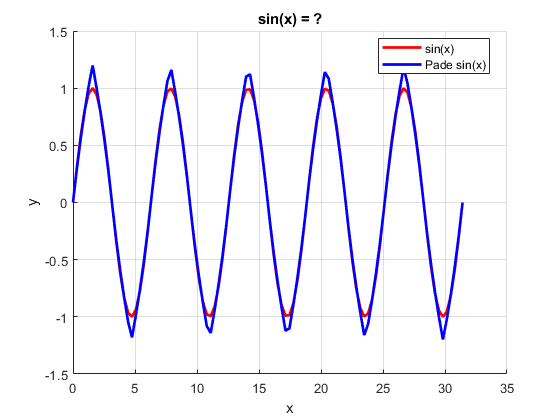

figure;
hold on;

plot(rad_range_pade, sin_points, 'r', 'LineWidth', 2, 'DisplayName', 'sin(x)');
plot(rad_range_pade, sinPade_points, 'b', 'LineWidth', 2, 'DisplayName', 'Pade sin(x)');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('sin(x) = ?');

hold off;


cos_points = zeros(size(rad_range_pade));
cosPade_points = zeros(size(rad_range_pade));

for i = 1:length(rad_range_pade)
    [cos_normal, cos_pade] = padeCos(rad_range_pade(i), 4, 5);
    cos_points(i) = cos_normal;
    cosPade_points(i) = cos_pade;
end

x = 0.0000000000000000e+00
Normal cox(x)                            = 1.0000000000000000e+00
cos(x) with Pade(4, 5)                 = 1.0000000000000000e+00

========= ERRORS =========
Normal vs. Pade(4, 5) = 0.0000000000000000e+00

x = 3.1733259127169627e-01
Normal cox(x)                            = 9.5007111774094544e-01
cos(x) with Pade(4, 5)                 = 8.4266071739306636e-01

========= ERRORS =========
Normal vs. Pade(4, 5) = 1.0741040034787908e-01

x = 6.3466518254339255e-01
Normal cox(x)                            = 8.0527025753105863e-01
cos(x) with Pade(4, 5)                 = 6.9317721086655115e-01

========= ERRORS =========
Normal vs. Pade(4, 5) = 1.1209304666450748e-01

x = 9.5199777381508877e-01
Normal cox(x)                            = 5.8005690957119826e-01
cos(x) with Pade(4, 5)                 = 5.5888235457631452e-01

========= ERRORS =========
Normal vs. Pade(4, 5) = 2.1174554994883743e-02

x = 1.2693303650867851e+00
Normal cox(x)                            

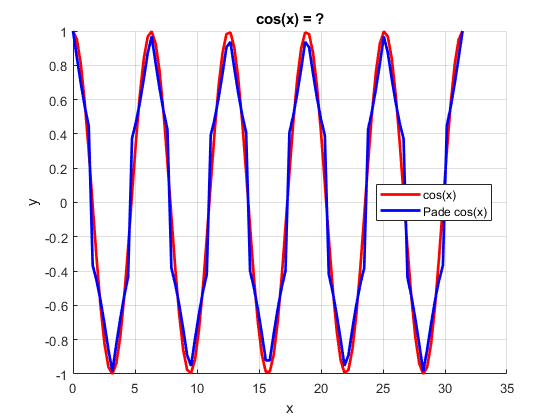


figure;
hold on;

disp_name = sprintf("Pade(%d, %d) sin(x)", m, k);
plot(rad_range_pade, cos_points, 'r', 'LineWidth', 2, 'DisplayName', 'cos(x)');
plot(rad_range_pade, cosPade_points, 'b', 'LineWidth', 2, 'DisplayName', 'Pade cos(x)');

legend('Location', 'best');
grid on;
xlabel('x');
ylabel('y');
title('cos(x) = ?');

hold off;

4. Input: numar in VF (simpla sau dubla precizie) si care returneaza reprezentarea binara pe componente: semn, exponent deplasat si mantisa (asa cum este reprezentat intern).

disp(numToBinary(1.0));

    "0"    ","    "01111111111"    ","    "00000000000000000…"



disp(numToBinary(-1.0));

    "1"    ","    "01111111111"    ","    "00000000000000000…"



disp(numToBinary(pi));

    "0"    ","    "10000000000"    ","    "10010010000111111…"



disp(numToBinary(exp(1)));

    "0"    ","    "10000000000"    ","    "01011011111100001…"



S1. Fie doua numere reale $x_1,x_2 \in \mathbb{R}, x_1 \ne x_2$. Consideram reprezentarile lor in VF $x_1^*$ si $x_2^*$ a.i. $x_1^* = fl(x1) = x1 * (1 + \delta_1), x_2^* = fl(x2) = x2 * (1 + \delta_2)$ si $|\delta_1| < \delta, |\delta_2| < \delta$. Cat de mic trebuie sa fie $\delta$ a.i. sa putem testa corect (in VF cu precizia masinii eps) daca $x1 \ne x2$.

In alte cuvinte, avem de demonstrat ca daca $x_1^* \ne x_2^* \Longleftrightarrow x_1 \ne x_2$. In cel mai rau caz, $x_2$ si $x_1$ sunt foarte apropiate: $x_2 = x_1 * (1 + margin)$, cu $margin$ foarte mic. Pentru ca conditia sa fie satisfacuta, avem de rezolvat urmatoarea ecuatie:


$$x_1 * (1 + \delta_1) \ne x_2*(1 + \delta_2) \Rightarrow x_1 * (1 + \delta_1) \ne x_1 * (1 + margin) * (1 + \delta_2)$$


In cel mai rau caz, nu doar ca $x_1$ si $x_2$ sunt foarte apropiate, dar se si apropie una de cealalta, iar acest caz se intampla cand $\delta_1 \gt 0 \land \delta_2 < 0$.

Avand conditia $|\delta_1| \lt \delta \land |\delta_2| \lt \delta$, putem considera $\delta$ ca o margine superioara pentru $\delta_1, \delta_2$. Astfel, considerand ca $x_1$ si $x_2$ se apropie una de cealalta, cu $x_1 \lt x_2$, rezolvarea este aceasta:


$$x_1 * (1 + \delta) < x_1 * (1 + margin) * (1 - \delta)$$



$$1 + \delta < (1 + margin) * (1 - \delta)$$



$$1 + \delta < 1 - \delta + margin - margin * \delta$$



$$2*\delta + margin * \delta < margin \Rightarrow \delta < \frac{margin}{margin + 2}$$


Tinand cont ca cea mai mica distanta intre 2 numere reprezentate in VF este aproximativ epsilonul masinii, rezulta maximul $\delta = \frac{eps}{eps + 2}$

margin = eps;
max_delta = margin / (margin + 2);

fprintf("Machine's epsilon: %.16e\n", eps);

Machine's epsilon: 2.2204460492503131e-16


fprintf("Max bound for delta: %.16e\n\n", max_delta);

Max bound for delta: 1.1102230246251565e-16




% Let's test with this theoretical bound
x1 = 1.0;
x2 = x1 * (1 + 2 * eps); % very close numbers

fprintf("x1 = %.16e, x2 = %.16e", x1, x2);

x1 = 1.0000000000000000e+00, x2 = 1.0000000000000004e+00

fprintf("x1 ?== x2: %d\n", x1 == x2);

x1 ?== x2: 0


fprintf("x2 - x1 = %.16e\n\n", x2 - x1);

x2 - x1 = 4.4408920985006262e-16




% Now let's see how accurate is this bound
tries = 1000;
successes = 0;

for i = 1:tries
    % numbers in [-max_delta, +max_delta]
    delta1 = (2 * rand - 1) * max_delta;
    delta2 = (2 * rand - 1) * max_delta;

    x1_fl = x1 * (1 + delta1);
    x2_fl = x2 * (1 + delta2);

    if x1_fl ~= x2_fl
        successes = successes + 1;
    end
end

fprintf("Succces rate with errors in bound %.16e: %2.f%%\n", max_delta, 100 * successes / tries);

Succces rate with errors in bound 1.1102230246251565e-16: 100%



% Now let's try a higher bound
double_max_delta = max_delta * 2;
successes = 0;

for i = 1:tries
    % numbers in [-double_max_delta, +double_max_delta]
    delta1 = (2 * rand - 1) * double_max_delta;
    delta2 = (2 * rand - 1) * double_max_delta;

    x1_fl = x1 * (1 + delta1);
    x2_fl = x2 * (1 + delta2);

    if x1_fl ~= x2_fl
        successes = successes + 1;
    end
end

fprintf("Succces rate with errors in bound %.16e: %2.f%%\n", double_max_delta, 100 * successes / tries);

Succces rate with errors in bound 2.2204460492503131e-16: 92%
